% Una resistenza di potenza è alimentata da un generatore DC. La potenza dissipata è
%     P = V^2 / R
% dove:
% - V è la tensione continua applicata ai capi del resistore;
% - R è la resistenza elettrica.
%
% Calcolare le incertezze di caso peggiore assoluta e relativa sulla misura di P.
% Successivamente, calcolare l'incertezza standard e l'incertezza estesa assolute su P.
% Si assuma che:
% - l'errore sulla misura di V abbia distribuzione RETTANGOLARE;
% - l'errore sulla misura di R abbia distribuzione TRIANGOLARE SIMMETRICA.
%
% Infine, si calcolino i coefficienti di sensibilità (assoluti e relativi).
%
% Attenzione: le PRIME CINQUE RISPOSTE sono condizione NECESSARIA per superare la prova scritta.
% Se una di queste risposte è errata o mancante, la prova scritta non può essere superata.

clear, clc
V = 12.00;      % tensione (volt)
R = 100.0;      % resistenza (ohm)
U_V = 0.10;      % incertezza di caso peggiore su V (volt), pdf rettangolare
U_R = 0.80;      % incertezza di caso peggiore su R (ohm), pdf triangolare simmetrica
k = 2.0;        % fattore di copertura

P = V^2/R

c_V = 2 * V/R % coefficiente di sensibilità ASSOLUTO di P rispetto a V
c_R = -1 * V^2/R^2 % coefficiente di sensibilità ASSOLUTO di P rispetto a R
U_P = abs(c_V) * U_V + abs(c_R) * U_R % incertezza assoluta di caso peggiore su P
Ur_P = U_P / abs(P) % incertezza relativa di caso peggiore su P
u_V = U_V / sqrt(3) % incertezza standard assoluta su V
u_R = U_R / sqrt(6) % incertezza standard assoluta su R
u_P = sqrt(c_V^2 * u_V^2 + c_R^2 * u_R^2) % incertezza standard assoluta su P
UE_P = u_P * k % incertezza estesa assoluta su P
cp = 2*normcdf(k) - 1 % probabilità di copertura dell'incertezza estesa
cr_V = 2 % coefficiente relativo di sensibilità di P rispetto a V
cr_R = -1 % coefficiente relativo di sensibilità di P rispetto a R
Cr = [cr_V, cr_R] % matrice dei coefficienti relativi di sensibilità di P rispetto a [V; R}

% Per ciascuna delle grandezze riportate qui sotto, eseguire la conversione
% nell'unità di misura indicata, esprimendo il risultato come valore numerico.
%
% Le quantità iniziali sono:
% - x1: velocità in km/h
% - x2: pressione in bar
% - x3: concentrazione in percentuale (%)
% - x4: energia in kilocalorie (kcal)
% - x5: temperatura in gradi Rankine (°R)
%
% Le unità di destinazione sono:
% - y1: velocità in m/s
% - y2: pressione in Pa
% - y3: concentrazione in ppm
% - y4: energia in joule (J)
% - y5: temperatura in gradi Celsius (°C)
%
% Per la conversione da Rankine a Celsius si ricorda che:
%   491.67 °R corrispondono a 0 °C
%   671.67 °R corrispondono a 100 °C
%
% Per la conversione del bar si ricordi che esso è circa uguale a
% un'atmosfera (1 atm = 101325 Pa) e che fu introdotto in modo che sia un
% multiplo/sottomultiplo decimale del pascal (il loro rapporto è una
% potenza di 10 esatta).
%
% Per la conversione della kilocaloria, si ricordi che per elevare di 10 °C
% una massa di 1 kg di acqua sono necessari 41840 J.
%
%==============================
% Dati, e codice che li genera (il codice NON VA MAI RIPORTATO NELLA SOLUZIONE)
clear

x1 = 72.0      % km/h
x2 = 1.20      % bar
x3 = 2.5       % percento
x4 = 150.0     % kcal
x5 = 600.0     % gradi Rankine

y1 = x1 * 1000 / 3600 % valore in m/s corrispondente a x1
y2 = x2 * 100000 % valore in Pa corrispondente a x2
y3 = x3 * 1e4 % valore in ppm corrispondente a x3
y4 = x4 * 4184 % valore in joule corrispondente a x4
y5 = (x5-491.67) * 100 / (671.67-491.67) % valore in gradi Celsius corrispondente a x5

% Si esprimano le unità di misura SI richieste in termini delle unità base.
% Ad esempio: 
% unita_velocita = m/s
%
% Si ricorda che le unità base sono metro (m), kilogrammo (kg), secondo (s),
% ampere (A), kelvin (K), mole (mol), candela (cd).
%
%==============================
% Dati, e codice che li genera (il codice NON VA MAI RIPORTATO NELLA SOLUZIONE)
clear, clc
syms m kg s A K mol % unità base del SI, esclusa la candela
who % elenco delle variabili simboliche da usare

N = kg * m/(s^2) % F = ma
J = N*m % L = F*dx
W = J/s % P = dL/dt
V = W/A % V = P/I
% V = E*dx
unita_E = V/m % esprimere l'unità SI del campo elettrico
% phi = E * dS
unita_phi = unita_E * m^2 % esprimere l'unità SI del flusso del campo elettrico
C = A*s % q = I * dt
F = C/V % esprimere il farad
% eps = C * d / S
unita_epsilon = F / m % esprimere l'unità SI della permittività dielettrica

% Suggerimento: si ricordi che: 
% 1) il flusso di un campo attraverso una superficie è il suo integrale sulla superficie stessa;
% 2) per la capacità vale la legge la legge C = q / V, da cui i = C*dv/dt;
% 3) per un condensatore piano ideale, la capacità è C = epsilon * S / d

% Una termocoppia tipo K è usata in un banco di taratura. La tensione v (in mV)
% è misurata da un voltmetro ad alta risoluzione (incertezza trascurabile), mentre
% la differenza di temperatura T (in °C) è letta da un termometro di riferimento
% affetto da piccoli errori a media nulla e i.i.d.
%
% Nel range 0–300 °C si adotta il modello inverso (quadratico):
%
%     T = a * v + b * v.^2
%
% dove a rappresenta la sensibilità "inversa" media e b
% corregge la non linearità. Tutta l'incertezza proviene da T.
%
% Calcolare:
% 1) la stima OLS dei parametri a_hat e b_hat;
% 2) le temperature stimate T_hat e i residui e_hat;
% 3) l'incertezza standard di tipo A (u0) sulle temperature;
% 4) la matrice di covarianza Sigma_theta di [a_hat; b_hat] e le incertezze standard u_a, u_b;
% 5) l'incertezza estesa UE_a di a_hat con fattore di copertura k assegnato; 
% 6) la relativa probabilità di copertura cp;
% 7) la stima T_star della temperatura corrispondente a v_star.
%
%==============================
% Dati, e codice che li genera (il codice NON VA MAI RIPORTATO NELLA SOLUZIONE)
clear, clc
v = [0.00; 2.06; 4.11; 6.18; 8.22; 10.25; 12.34];  % tensione in mV (senza incertezza)
T = [ 0.5; 49.2; 100.7; 149.3; 200.6; 249.5; 300.8]; % °C (misure rumorose)
k = 2.0;                      % fattore di copertura
v_star = 7.00;                % tensione in mV a cui stimare la temperatura
plot(v,T,'-o'), grid, xlabel('tensione / mV'), ylabel('temperatura misurata / °C') % grafico

A = [v v.^2]
Q = (A'*A)^-1;
C = Q*A';
P = A*C;
theta_hat = C * T
a_hat = theta_hat(1,1) % stima OLS di a
b_hat = theta_hat(2,1) % stima OLS di b
T_hat = A * theta_hat % stime OLS di T nelle tensioni v
e_hat = T - T_hat % residui
SSR = sum(e_hat.^2)
ni = size(v,1) - size(theta_hat, 1)
u0 = sqrt(SSR/ni) % incertezza standard di tipo A delle temperature
Sigma_theta = u0^2 * Q % matrice covarianza di [a_hat; b_hat]
u_theta = sqrt(diag(Sigma_theta));
u_a = u_theta(1,1) % incertezza standard su a_hat
u_b = u_theta(2,1) % incertezza standard su b_hat
UE_a = u_a * k % incertezza estesa di a_hat
cp = 2*tcdf(k, ni) - 1 % probabilità di copertura dell'incertezza estesa
T_star = a_hat * v_star + b_hat * v_star^2 % stima della temperatura quando si misura v_star

% Per le quantità stimate o calcolate nel quesito precedente,
% indicare l'unità di misura corretta, esprimendola come stringa.
% Usare la notazione testuale ("mV", "°C", "°C/mV", "adim", ecc.).

unita_a = "°C/mV" % unità di misura di a_hat
unita_b = "°C/mV^2" % unità di misura di b_hat
unita_u0 = "°C" % unità di misura di u0
unita_u_a = unita_a % unità di misura di u_a
unita_u_b = unita_b % unità di misura di u_b
unita_cp = "adim" % unità di misura di cp

% Un voltmetro ha portata VFS = 100 mV e resistenza interna infinita. Si
% vuole elevare la sua portata di k volte, portandola a VFS1 = 1 V, e la
% sua resistenza interna a RV1 = 10 Mohm, con il circuito in figura. Il
% circuito è fatto per dividere la tensione in ingresso Vx per il fattore
% k, cioè per moltiplicarla per il rapporto di partizione r = 1/k.
%
% Determinare i valori delle resistenze RV e Rp.
% 
% Sapendo che RV sarà realizzata con un errore massimo del 2% in più o in
% meno, e Rp sarà realizzata con un errore massimo del 3% in più o in meno,
% calcolare con che errore relativo massimo in più o in meno sarà
% realizzato il rapporto di partizione r dalla rete di resistenze.
%
% (Nota esplicativa: si richiede semplicemente di progettare il partitore di
% tensione realizzato da Rp e RV, e di calcolare l'incertezza relativa di
% caso peggiore del rapporto di
% partizione.)
%
%==============================
% Dati, e codice che li genera (il codice NON VA MAI RIPORTATO NELLA SOLUZIONE)
clear, clc
VFS = 0.1; % fondo scala del volmetro (V)
VFS1 = 1; % fondo scala del voltmetro con la rete di resistenze
RV1 = 10e6; % resistenza del voltmetro con la rete di resistenze
Ur_RV = 0.02; % WCU con cui è realizzata RV
Ur_Rp = 0.03; % WCU con cui è realizzata Rp

k = VFS1 / VFS % fattore di elevamento della portata

k = 10

RV = RV1 / k % resistenza RV

RV = 1000000

Rp = (k-1)*RV % resistenza Rp

Rp = 9000000


syms RV_ Rp_ real
RV1_ = RV_ + Rp_;
k_ = RV1_/RV_;
simplify(diff(k_, RV_) * RV_ / k_)

$$ans = -\frac{\mathrm{Rp\_}}{\mathrm{RV\_}+\mathrm{Rp\_}}$$

simplify(diff(k_, Rp_) * Rp_ / k_)

$$ans = \frac{\mathrm{Rp\_}}{\mathrm{RV\_}+\mathrm{Rp\_}}$$


cr_RV = - Rp / (Rp + RV) % coefficiente relativo di sensibilità di r rispetto a RV

cr_RV = -0.9000

cr_Rp = - cr_RV % coefficiente relativo di sensibilità di r rispetto a Rp

cr_Rp = 0.9000

Ur_r = abs(cr_RV)*Ur_RV + abs(cr_Rp)*Ur_Rp % WCU di r = 1/k

Ur_r = 0.0450

% A un filtro LR si collegano generatore e oscilloscopio come in figura. Si
% misura sia la risposta al gradino, sia la risposta a un segnale
% sinusoidale (FRF con sinusoide single-tone).
%
% Quando si misura la risposta al gradino, l'ampiezza del gradino
% di tensione vgen(t) è pari a Vin.
%
% Quando si misura la FRF, la sinusoide in ingresso v1(t) ha valore
% picco-picco Vpp1, e il suo primo passaggio per lo zero è all'istante t1,
% come in figura.

clear, clc
R = 200 % resistenza del circuito (ohm)

R = 200

L = 1e-4 % induttanza del circuito (H)

L = 1.0000e-04

s = tf('s') % variabile s della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.
Model Properties


f = 2e5 % frequenza del segnale sinusoidale (Hz)

f = 200000

Vin = 3.5 % ampiezza del gradino vgen(t), nella misura di risposta al gradino

Vin = 3.5000

Vpp1 = 4 % valore picco-picco della sinusoide in ingresso v1(t), nella misura di FRF

Vpp1 = 4

t1 = 9e-7 % istante del primo passaggio per lo zero di v1(t), nella misura di FRF

t1 = 9.0000e-07

w = 2*pi*f

w = 1.2566e+06


Rgen = 50;
R1 = R + Rgen;
k1 = R/R1

k1 = 0.8000

tau = L/R

tau = 5.0000e-07

tau1 = L/R1

tau1 = 4.0000e-07

Hdot1 = R / (R1 + s*L) % funzione di trasferimento misurando la risposta al gradino, calcolata in s

Hdot1 =
 
       200
  --------------
  0.0001 s + 250
 
Continuous-time transfer function.
Model Properties


% Hdot1 = k1 / (1 + s*tau1)
fc1 = 1/(2*pi*tau1) % frequenza di taglio teorica di Hdot1 (Hz)

fc1 = 3.9789e+05

% th del valor finale lim w->0 sR(s) con R(s) = H1(s) * 1/s => H(w->0) = k1
Vout = Vin * k1 % valore finale della risposta al gradino misurata all'uscita

Vout = 2.8000

Hdot = R / (R + s*L) % funzione di trasferimento misurando la risposta a una sinusoide single-tone, calcolata in s

Hdot =
 
       200
  --------------
  0.0001 s + 200
 
Continuous-time transfer function.
Model Properties


fc = 1/(2*pi*tau) % frequenza di taglio teorica di Hdot (Hz)

fc = 3.1831e+05

H = 1 / sqrt(1 + (f/fc)^2)% risposta di ampiezza al segnale sinusoidale, alla frequenza f

H = 0.8467

phiH = -atan(f/fc) % risposta di fase al segnale sinusoidale, alla frequenza f

phiH = -0.5610

H_dB = 20*log10(H)

H_dB = -1.4451

phiH_deg = phiH * 180 / pi

phiH_deg = -32.1419

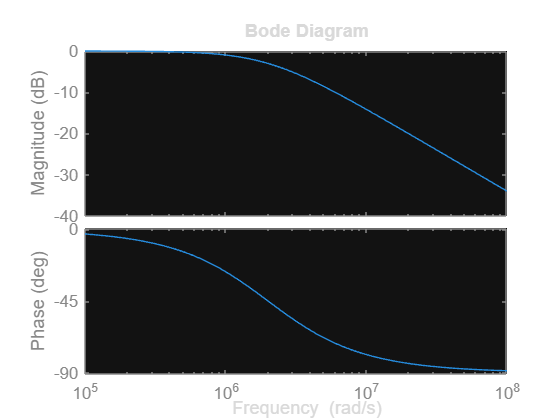

bode(Hdot)

Vpp2 = Vpp1 * H % tensione picco-picco della sinusoide in uscita

Vpp2 = 3.3869

% phiH = w * dt
dt = phiH / w % shift temporale tra le sinusoidi in ingresso e in uscita, con lo stesso segno di phiH

dt = -4.4642e-07

% dt = t1 - t2
t2 = t1 - dt % istante di primo passaggio dallo zero della sinusoide in uscita

t2 = 1.3464e-06

%
%==============================
% Note 
% La risposta al gradino è misurata osservando la tensione v2(t), e
% considerando vgen(t) un gradino ideale. La FRF è misurata confrontando le
% tensioni v2(t) e v1(t).
%
% La resistenza Rgen ha il valore standard del generatore utilizzato in
% laboratorio.

% Con riferimento al circuito LR precedente, e alle sinusoidi misurate in
% ingresso e in uscita, si misuri la risposta di fase e la frequenza di
% taglio, valutando l'incertezza STANDARD. Gli errori su t1, t2, f sono
% indipendenti.

clear, clc
t1 = 10e-7 % istante di attraversamento dello zero della sinusoide in ingresso (s)

t1 = 1.0000e-06

t2 = 15e-7 % istante di attraversamento dello zero della sinusoide in uscita (s)

t2 = 1.5000e-06

f = 1e5 % frequenza della sinusoide (Hz)

f = 100000

R = 120 % valore della resistenza (ohm)

R = 120


U_t1 = 5e-10 % incertezza assoluta nella misura di t1

U_t1 = 5.0000e-10

U_t2 = 6e-10 % incertezza assoluta nella misura di t2

U_t2 = 6.0000e-10


Ur_f = 0.5e-3 % incertezza relativa nella misura di f

Ur_f = 5.0000e-04

Ur_R = 1e-3 % incertezza relativa nella misura di R

Ur_R = 1.0000e-03


w = 2*pi*f

w = 6.2832e+05

dt = t1-t2

dt = -5.0000e-07

phiH = w*dt % risposta di fase misurata

phiH = -0.3142

% phiH = -atan(f/fc) => f/fc = tan(-phiH)
fc = f/tan(-phiH) % frequenza di taglio misurata dalla risposta di fase

fc = 3.0777e+05

u_dt = sqrt(U_t1^2/3 + U_t2^2/3)

u_dt = 4.5092e-10

ur_dt = u_dt / abs(dt) % incertezza standard relativa di dt

ur_dt = 9.0185e-04

ur_phiH = sqrt(Ur_f^2/3 + ur_dt^2) % incertezza standard relativa di phiH

ur_phiH = 9.4692e-04


syms dt_ f_ real
w_ = 2*pi*f_;
phi_ = w_ * dt_;
fc_ = f_ / tan(-phi_)

$$fc\_ = -\frac{\mathrm{f\_}}{\tan\left(2\,\pi \,\mathrm{dt\_}\,\mathrm{f\_}\right)}$$

simplify(diff(fc_, dt_) * dt_ / fc_)

$$ans = -\frac{4\,\pi \,\mathrm{dt\_}\,\mathrm{f\_}}{\sin\left(4\,\pi \,\mathrm{dt\_}\,\mathrm{f\_}\right)}$$

simplify(diff(fc_, f_) * f_ / fc_)

$$ans = \frac{\sin\left(4\,\pi \,\mathrm{dt\_}\,\mathrm{f\_}\right)-4\,\pi \,\mathrm{dt\_}\,\mathrm{f\_}}{\sin\left(4\,\pi \,\mathrm{dt\_}\,\mathrm{f\_}\right)}$$

cr_fc_dt = -4*pi*dt*f / sin(4*pi*dt*f) % coefficiente di sensibilità relativo di fc rispetto a dt

cr_fc_dt = -1.0690

cr_fc_f = (sin(4*pi*dt*f) - 4*pi*dt*f) / sin(4*pi*dt*f) % coefficiente di sensibilità relativo di fc rispetto a f

cr_fc_f = -0.0690

Cr = [cr_fc_dt cr_fc_f] % matrice dei coefficienti relativi di sensibilità di fc rispetto a x = [dt;f]

Cr =    -1.0690   -0.0690


ur_fc_matrix = [ur_dt; Ur_f/sqrt(3)];
ur_fc = sqrt(Cr.^2 * ur_fc_matrix.^2) % incertezza standard di fc

ur_fc = 9.6425e-04

% tau = 1/(2*pi*fc) = L/R => L = R/wc
wc = 2*pi*fc

wc = 1.9338e+06

L = R/wc % induttanza del circuito LR misurata dalla risposta di ampiezza phiH

L = 6.2055e-05

ur_L = sqrt(Ur_R^2/3 + ur_fc^2) % incertezza standard di L

ur_L = 0.0011

% Si misura il valore efficace AC di una forma d'onda non sinusoidale (distorta) 
% con il multimetro Agilent 34401A, le cui caratteristiche sono in figura. Calcolare 
% l'incertezza di caso peggiore.
% 
% Fare riferimento ai dati "1 Year". La specifica sulla temperatura è 
% da ignorare (temperatura compresa tra 18 e 28 °C). Tutti i dati sono in unità 
% SI (volt, hertz, ecc.)

clear, clc
V = -0.125 % valore efficace misurato

V = -0.1250

f = 15e3 % frequenza del segnale

f = 15000

CF = 2.5 % crest factor del segnale

CF = 2.5000


VFS = 1 % portata su cui è misurata la forma d'onda (scegliere la minima possibile per lo strumento)

VFS = 1

Ur_reading_pc = 0.06 % "reading error percentuale": il numero scritto nelle specifiche

Ur_reading_pc = 0.0600

U_range_FS_pc = 0.03 % "range error percentuale": il numero scritto nelle specifiche

U_range_FS_pc = 0.0300

Ur_reading_CF_pc = 0.15 % "CF reading error percentuale": il numero scritto nelle specifiche

Ur_reading_CF_pc = 0.1500

BW = 1e6 % banda dello strumento

BW = 1000000

Ur_reading_BW = CF^2 * f / (4*pi*BW) % "BW reading error", incertezza relativa dovuta alla larghezza di banda, da formula del manuale

Ur_reading_BW = 0.0075

U_reading = Ur_reading_pc / 100 * abs(V) % incertezza assoluta da "reading error"

U_reading = 7.5000e-05

U_range = U_range_FS_pc / 100 * VFS % incertezza assoluta da "range error"

U_range = 3.0000e-04

U_reading_CF = Ur_reading_CF_pc / 100 * abs(V) % incertezza assoluta da "CF reading error"

U_reading_CF = 1.8750e-04

U_reading_BW = Ur_reading_BW * abs(V) % incertezza assoluta da "BW reading error"

U_reading_BW = 9.3255e-04

U_V = U_reading + U_range + U_reading_CF + U_reading_BW % incertezza assoluta totale

U_V = 0.0015

Ur_V = U_V / abs(V) % incertezza relativa totale

Ur_V = 0.0120

Ur_V_pc = Ur_V * 100 % incertezza relativa percentuale

Ur_V_pc = 1.1960

incertezza_relativa = "1.2%" % la Ur_V_pc scritta come stringa

incertezza_relativa = "1.2%"